clear all
close all
addpath(genpath('/data/drive/postdoc/Project3_pedlr/pedlr/code/simulation/ondrejs_corner'));
addpath('/home/ondrej/pl1/Behavioural/models')
addpath(genpath('~/tools/matlab'))
iter = 10;
domain = 0; % 0 = positive domain; -1 = negative domain   
ncues = 3;
noparams = 4;
clear('out', 'C')
params = {'pi', 'al1', 'al2', 'beta'}

params = 1×4 cell array
    {'pi'}    {'al1'}    {'al2'}    {'beta'}


noruns = 1;

limits= [0 1; 0 1; 0 1; 0 20];
D = [];

for nr = 1:noruns
t = 1;
for pi = 0.1:0.2:0.9
    for al1 = 0.1:0.2:0.9
        for al2 = 0.1:0.2:0.9
            for beta = 0.5:2:9.5
                disp(['run ' num2str(nr) ' pi=' num2str(pi) ' al1=' num2str(al1) ' al2=' num2str(al2) ' beta=' num2str(beta)])
                D.true(nr,t,1) = pi;
                D.true(nr,t,2) = al1;
                D.true(nr,t,3) = al2;
                D.true(nr,t,4) = beta;
           
                % Generate distributions of rewards
                n = 1200;
                for i = 1:n
                    C(1, i) = betarnd(1.66, 3.33)*100 + domain*100; 
                    C(3, i) = betarnd(3.33, 1.66 )*100 + domain*100;
                    C(2, i) = betarnd(2.5, 2.5)*100 + domain*100;
                end
                
                % visually check distributions
                
                
                
                %%
                out = [];
                out.model_name = 'pedlr3_model';
                
                out.ncues =ncues;
                ntrls_each = 200; %should be 100 of each choice
                tr_types = nchoosek(1:3,2);
                tr_types = [tr_types; [tr_types(:,2) tr_types(:,1)]];
                out.sch = (repmat(tr_types,ntrls_each,1));
                ntrls = size(out.sch,1);
                %add force choice
                out.sch(1:0.2*ntrls,4) = 1;
                out.sch(0.2*ntrls+1:end,4) = 0;
                out.sch = out.sch(randperm(ntrls),:);
                
                %select 600 rewards from the 10k generated above
                C= C(:,randperm(n))';
                out.R = C(1:ntrls,:);
                out.Q = [50 50 50];
                %out.Q = [-50 -50 -50];
                
                p.pi = pi;
                p.al2 =al2;
                p.al1 = al1;
                p.beta   = beta;
                out = pedlr3_model(p, out);
                
                data.ch = out.ch;
                data.R  = out.R;
                
                for i = 1:noparams %SPECIFIED to 3 params
                    while true
                        initial_val(i) = rand * limits(i,2);
                        if initial_val(i) > limits(i,1) && initial_val(i) < limits(i,2)
                            break
                        end
                    end
                end
                
                lb = limits(:,1)';
                ub = limits(:,2)';
                
                
                X0(1:noparams) = initial_val;
                cues=[];
                out.data = data;
                out.Q = [50 50 50];
                [X, err] = bads(@pedlr_model_error, X0, lb, ub, [], [], [], [], out);
                D.est(nr,t,:) = X;
                D.err(nr) = err;
                X
                t=t+1;
             end
        end
    end
    
end
end

run 1 pi=0.1 al1=0.1 al2=0.1 beta=0.5


Beginning optimization of a STOCHASTIC objective fcn.

 Iteration    f-count      E[f(x)]        SD[f(x)]           MeshScale          Method          Actions
     0           2         2268.37             NaN               1                              Uncertainty test
     0          22         833.522             NaN               1            Initial mesh      


save(['pr_pedlr3_' num2str(noruns) 'runs.mat']);


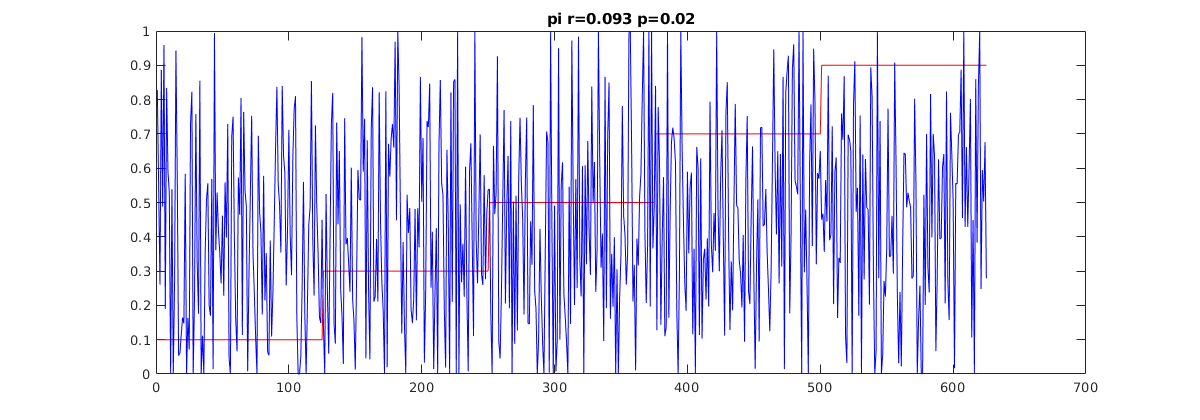

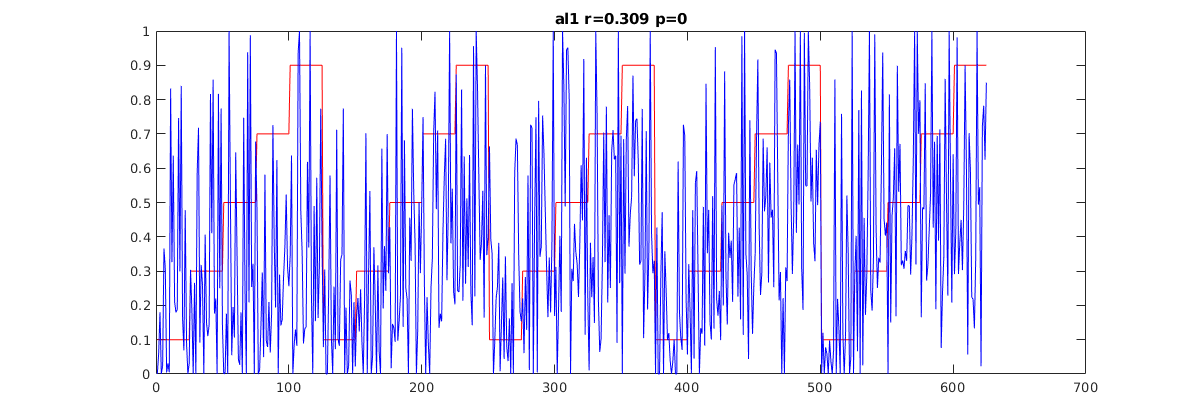

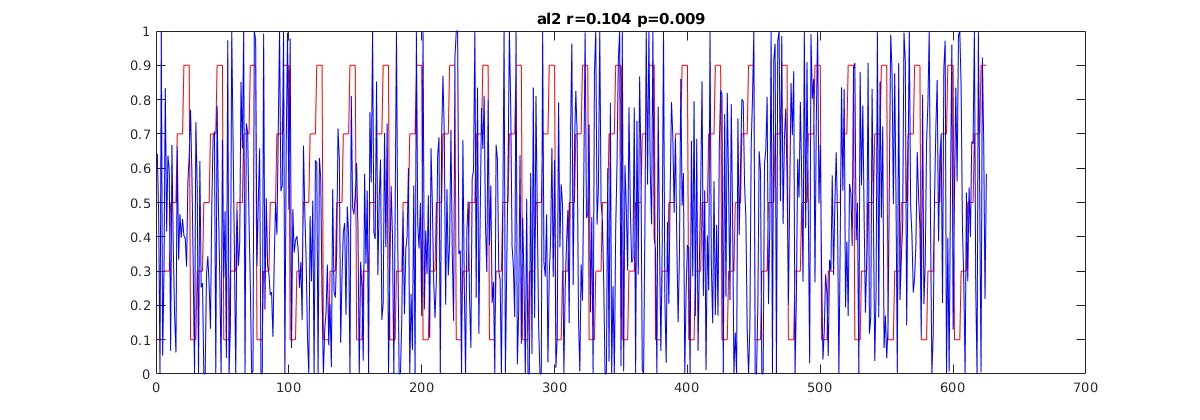

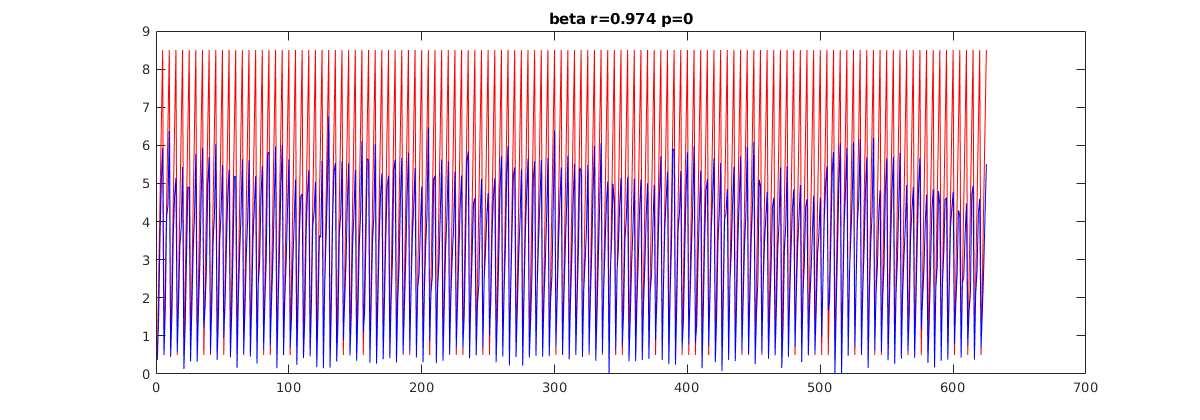

load(['pr_pedlr3_' num2str(noruns) 'runs.mat']);
minerr  = find(D.err==min(D.err));
for np = 1:noparams
    A = [squeeze(D.true(minerr,:,np))' squeeze(D.est(minerr,:,np))'];
    [rr, pp] = corr(A(:,1), A(:,2));    
    f=figure;
    plot(A(:,1), 'Color', 'r');
    hold on 
    plot(A(:,2), 'Color', 'b');
    %legend({'true', 'estimated'});
    title([params{np} ' r=' num2str(round(rr,3)), ' p=' num2str(round(pp,3))]);
    f.Position(3) = 1200;
end